E_k = 250;

fplot(@(E) tanh(E/E_k), [0,1000],'r')
hold on
fplot(@(E) E/(E_k+E), [0,1000],'b')

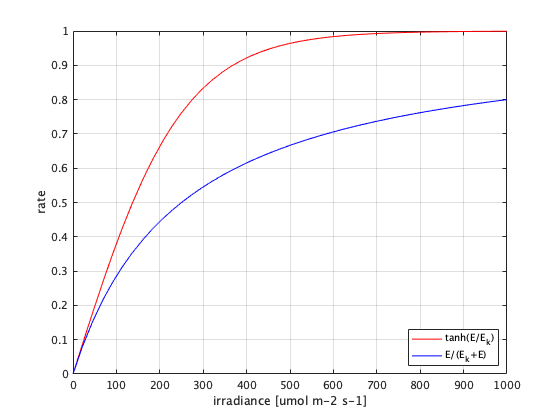

hold off
grid on
xlabel('irradiance [umol m-2 s-1]');
ylabel('rate');
legend('tanh(E/E_k)','E/(E_k+E)','Location','southeast');

% saveas(gcf,'seagrass_E.png')


Ea = 51*1000;     %水の昇華熱?[J mol-1]
Rgas = 8.31446; %[J K-1 mol-1] Gas constant
A  = 1/exp(-Ea/(Rgas*303));   %25degCで1になるようなA(本当はArrhenius plotで導出)
dH = 2803*1000/6;    %化学式から求めた反応熱
dS = dH/340;    %340Kで活性が1/(1+A)倍になるためのエントロピー

range = [270 320];

fplot(@(T) A*exp(-Ea/(Rgas*T)) ,range)

hold on
fplot(@(T) 1/(1+A*exp((T*dS-dH)/(Rgas*T))) ,range)

hold on
fplot(@(T) A*exp(-Ea/(Rgas*T))/(1+A*exp((T*dS-dH)/(Rgas*T))) ,range)

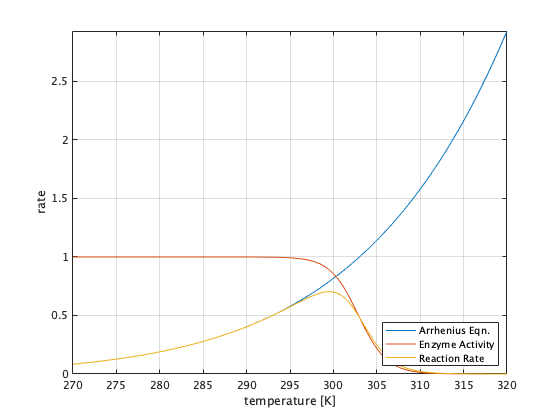

hold off
grid on
xlabel('temperature [K]');
ylabel('rate');
legend('Arrhenius Eqn.','Enzyme Activity','Reaction Rate','Location','southeast');

% saveas(gcf,'seagrass_T.png')